clear;
clc;
format long
%% Load Dataset
Xtrain = load('Xtrain.mat').Xtrain;
Ytrain = load('Ytrain.mat').Ytrain;
Xtest = load('Xtest.mat').Xtest;
Ytest = load('Ytest.mat').Ytest;
cvKF5 = load('cvKF5.mat','cvKF5').cvKF5;
cvKF10 = load('cvKF10.mat','cvKF10').cvKF10;
cvKF20 = load('cvKF20.mat','cvKF20').cvKF20;
%% Load MRMR
MRMR = load('MRMR.mat').MRMR;
idxMRMR = MRMR(1,:);
scores = MRMR(2,:);
%% K vs Num. Features (K-Fold = 5)
Ks =[1:2:51];
knnMRMR_5 = zeros(12,length(Ks));
AUC_5 = zeros(12,length(Ks));
F1_5 = zeros(12,length(Ks));

for f=1:12
    for k=1:length(Ks)
        knnMRMR_CV = fitcknn(Xtrain(:,idxMRMR(1:f)),Ytrain,'NumNeighbors',k,'Standardize',1,'CVPartition',cvKF5);
        [knnMRMR_pred, scores] = kfoldPredict(knnMRMR_CV);
        knnMRMR_5(f,k) = mean(Ytrain == knnMRMR_pred);
        [~,~,~,AUCknn_n] = perfcurve(Ytrain,scores(:,1),'Necrosis');
        [~,~,~,AUCknn_s] = perfcurve(Ytrain,scores(:,2),'Stroma');
        [~,~,~,AUCknn_t] = perfcurve(Ytrain,scores(:,3),'Tumor');
        AUC_5(f,k) = (AUCknn_n + AUCknn_s + AUCknn_t)/3;
        tpNk = sum(ismember(Ytrain,'Necrosis') & ismember(knnMRMR_pred,'Necrosis'));
        tpSk = sum(ismember(Ytrain,'Stroma') & ismember(knnMRMR_pred,'Stroma'));
        tpTk = sum(ismember(Ytrain,'Tumor') & ismember(knnMRMR_pred,'Tumor'));
        fpNk = sum(ismember(knnMRMR_pred,'Necrosis')) - tpNk;
        fpSk = sum(ismember(knnMRMR_pred,'Stroma')) - tpSk;
        fpTk = sum(ismember(knnMRMR_pred,'Tumor')) - tpTk;
        fnNk = sum(ismember(Ytrain, 'Necrosis')) - tpNk;
        fnSk = sum(ismember(Ytrain, 'Stroma')) - tpSk;
        fnTk = sum(ismember(Ytrain, 'Tumor')) - tpTk;
        f1Nk = tpNk/(tpNk + (fpNk+fnNk)/2);
        f1Sk = tpSk/(tpSk + (fpSk+fnSk)/2);
        f1Tk = tpTk/(tpTk + (fpTk+fnTk)/2);
        F1_5(f,k) = (f1Nk + f1Sk + f1Tk)/3;

    end
end
%% Heatmap Accuracy
xvals_numF = num2cell(Ks);
yvals_k = num2cell([1:12]);
figure;
h5 = heatmap(xvals_numF, yvals_k, knnMRMR_5,'Colormap', jet, 'CellLabelColor','none');
title('KNN: Accruacy 5-Fold');
h5.XLabel = 'K_K_N_N';
h5.YLabel = 'Num of Features';

%% Heatmap AUC
figure;
h = heatmap(xvals_numF, yvals_k, AUC_5,'Colormap', jet, 'CellLabelColor','none');
title('KNN: AUC 5-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';
%% Heatmap F1
figure;
h = heatmap(xvals_numF, yvals_k,F1_5,'Colormap', jet, 'CellLabelColor','none');
title('KNN: F1 Score 5-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';

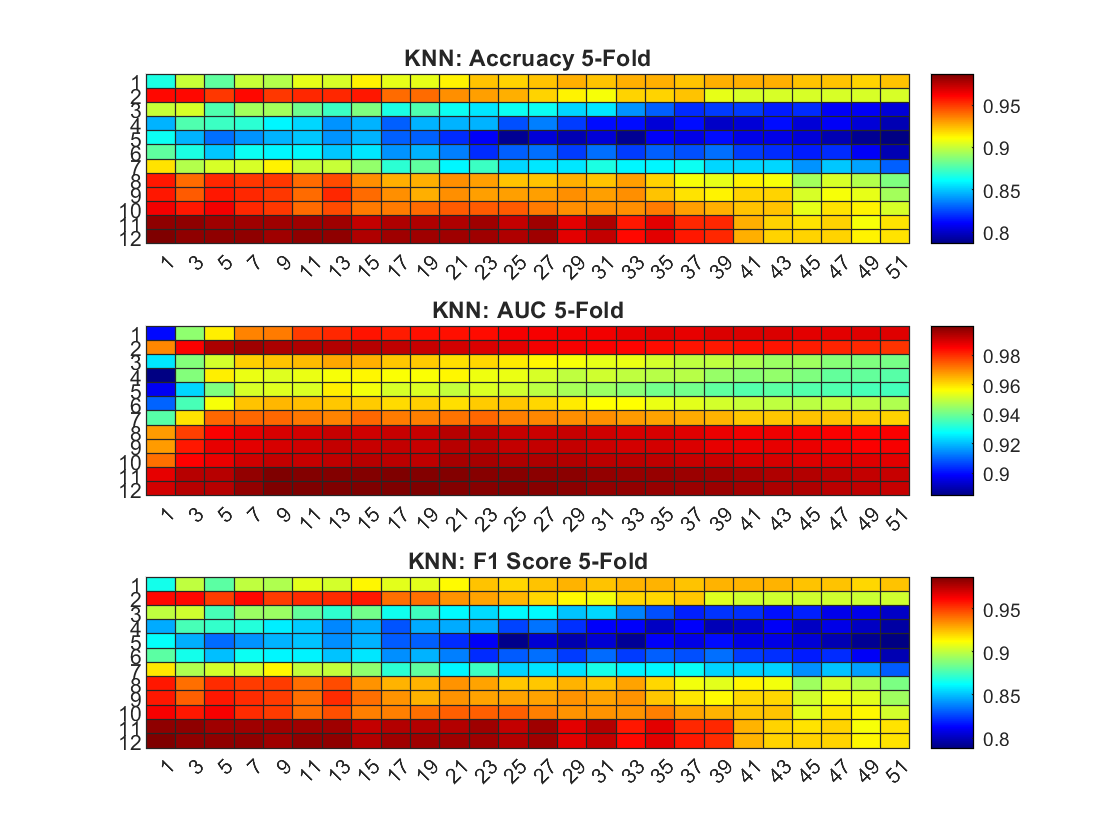

figure;
xvals_numF = num2cell(Ks);
yvals_k = num2cell([1:12]);
subplot(3,1,1);
heatmap(xvals_numF, yvals_k, knnMRMR_5,'Colormap', jet, 'CellLabelColor','none');
title('KNN: Accruacy 5-Fold');
h5.XLabel = 'K_K_N_N';
h5.YLabel = 'Num of Features';
subplot(3,1,2);
heatmap(xvals_numF, yvals_k, AUC_5,'Colormap', jet, 'CellLabelColor','none');
title('KNN: AUC 5-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';
subplot(3,1,3);
heatmap(xvals_numF, yvals_k,F1_5,'Colormap', jet, 'CellLabelColor','none');
title('KNN: F1 Score 5-Fold');

h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';

## K vs Num. Features (K-Fold = 10)


Ks =[1:2:51];
knnMRMR_10 = zeros(12,length(Ks));
AUC_10 = zeros(12,length(Ks));
F1_10 = zeros(12,length(Ks));

for f=1:12
    for k=1:length(Ks)
        knnMRMR_CV = fitcknn(Xtrain(:,idxMRMR(1:f)),Ytrain,'NumNeighbors',k,'Standardize',1,'CVPartition',cvKF10);
        [knnMRMR_pred, scores] = kfoldPredict(knnMRMR_CV);
        knnMRMR_10(f,k) = mean(Ytrain == knnMRMR_pred);
        [~,~,~,AUCknn_n] = perfcurve(Ytrain,scores(:,1),'Necrosis');
        [~,~,~,AUCknn_s] = perfcurve(Ytrain,scores(:,2),'Stroma');
        [~,~,~,AUCknn_t] = perfcurve(Ytrain,scores(:,3),'Tumor');
        AUC_10(f,k) = (AUCknn_n + AUCknn_s + AUCknn_t)/3;
        tpNk = sum(ismember(Ytrain,'Necrosis') & ismember(knnMRMR_pred,'Necrosis'));
        tpSk = sum(ismember(Ytrain,'Stroma') & ismember(knnMRMR_pred,'Stroma'));
        tpTk = sum(ismember(Ytrain,'Tumor') & ismember(knnMRMR_pred,'Tumor'));
        fpNk = sum(ismember(knnMRMR_pred,'Necrosis')) - tpNk;
        fpSk = sum(ismember(knnMRMR_pred,'Stroma')) - tpSk;
        fpTk = sum(ismember(knnMRMR_pred,'Tumor')) - tpTk;
        fnNk = sum(ismember(Ytrain, 'Necrosis')) - tpNk;
        fnSk = sum(ismember(Ytrain, 'Stroma')) - tpSk;
        fnTk = sum(ismember(Ytrain, 'Tumor')) - tpTk;
        f1Nk = tpNk/(tpNk + (fpNk+fnNk)/2);
        f1Sk = tpSk/(tpSk + (fpSk+fnSk)/2);
        f1Tk = tpTk/(tpTk + (fpTk+fnTk)/2);
        F1_10(f,k) = (f1Nk + f1Sk + f1Tk)/3;

    end
end
%% Heatmap Accuracy
xvals_numF = num2cell(Ks);
yvals_k = num2cell([1:12]);
figure;
h5 = heatmap(xvals_numF, yvals_k, knnMRMR_10,'Colormap', jet, 'CellLabelColor','none');
title('Acuuracy 10-Fold');
h5.XLabel = 'K_K_N_N';
h5.YLabel = 'Num of Features';
%% Heatmap AUC
figure;
h2 = heatmap(xvals_numF, yvals_k, AUC_10,'Colormap', jet, 'CellLabelColor','none');
title('AUC 10-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';
%% Heatmap F1
figure;
h = heatmap(xvals_numF, yvals_k,F1_10,'Colormap', jet, 'CellLabelColor','none');
title('F1 Score 10-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';

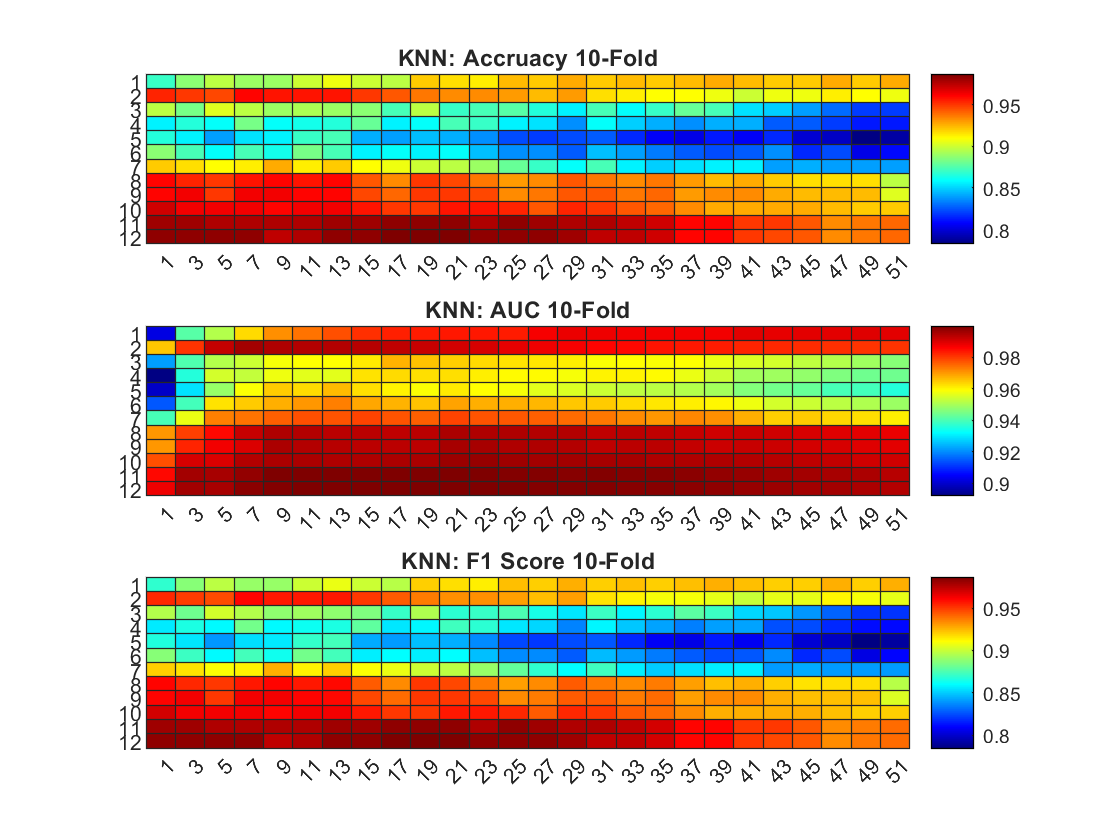

figure;
xvals_numF = num2cell(Ks);
yvals_k = num2cell([1:12]);
subplot(3,1,1);
heatmap(xvals_numF, yvals_k, knnMRMR_10,'Colormap', jet, 'CellLabelColor','none');
title('KNN: Accruacy 10-Fold');
h5.XLabel = 'K_K_N_N';
h5.YLabel = 'Num of Features';
subplot(3,1,2);
heatmap(xvals_numF, yvals_k, AUC_10,'Colormap', jet, 'CellLabelColor','none');
title('KNN: AUC 10-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';
subplot(3,1,3);
heatmap(xvals_numF, yvals_k,F1_10,'Colormap', jet, 'CellLabelColor','none');
title('KNN: F1 Score 10-Fold');

h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';

## External Validtion


knnMRMR_flat_1 = reshape(knnMRMR_10,[],1);
knnMRMR_flat = sort(unique(knnMRMR_flat_1), 'descend');
fk = [];
knnMRMR_CV_preds = [];
for a=1:10
    inds = find(knnMRMR_10 == knnMRMR_flat(a));
    for i = 1:length(inds)
        [f,k] = ind2sub(size(knnMRMR_10),inds(i));
        fk = [fk; f, k];
        knnMRMR_CV_preds = [knnMRMR_CV_preds, knnMRMR_flat(a)];
    end
end
%%
knnMRMR_preds = [];
for i=1:length(fk)
    f = fk(i,1);
    k = fk(i,2);
    knnMRMR = fitcknn(Xtrain(:,idxMRMR(1:f)),Ytrain,'NumNeighbors',Ks(k),'Standardize',1);
    pred = predict(knnMRMR, Xtest(:,idxMRMR(1:f)));
    knnMRMR_preds = [knnMRMR_preds, mean(pred==Ytest)]; % accuracy
    
end


## Plot Acuracy

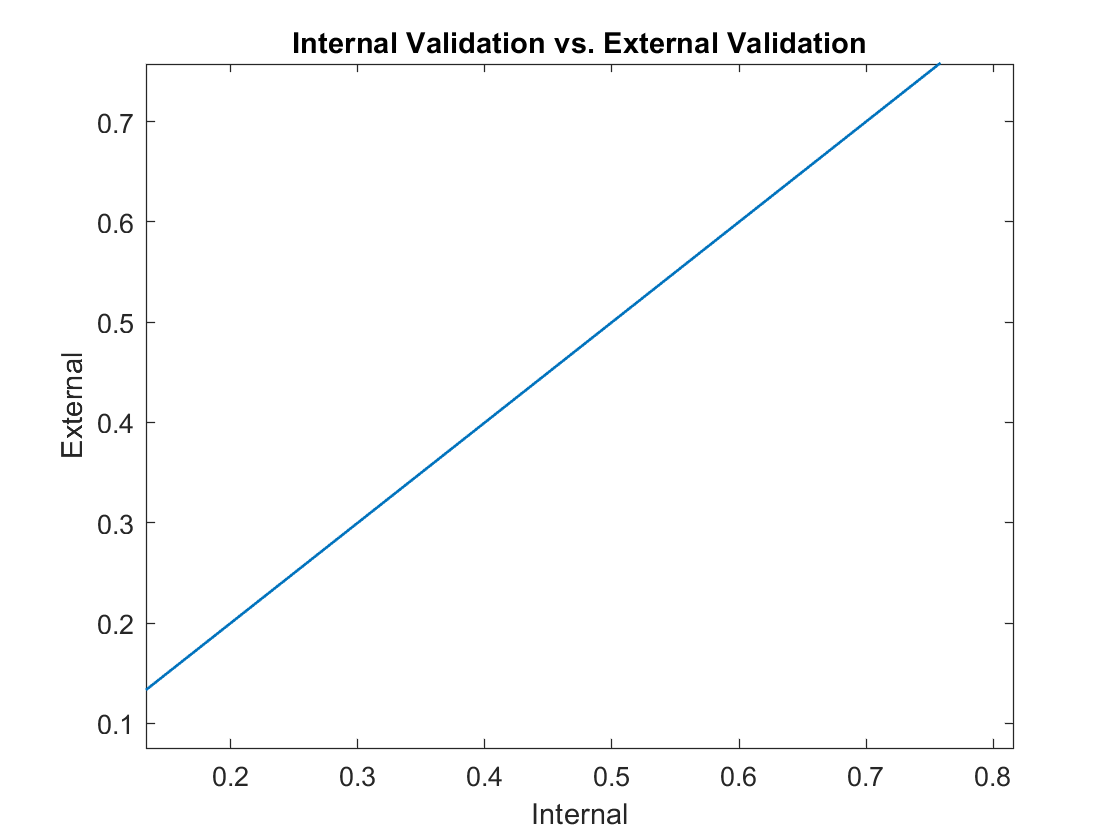


figure;
x = [0:1];
y = x;
plot(x, y,'Linewidth',1);
hold on
scatter(knnMRMR_CV_preds,knnMRMR_preds,'+','Linewidth',1);
title('Internal Validation vs. External Validation');
xlabel('Internal');
ylabel('External');

## CM


% # features: 12, k: 3
master = [knnMRMR_preds.', fk];
master = sortrows(master,1,'descend');
bf = master(1,2);
bk = Ks(master(1,3));
knnMRMR = fitcknn(Xtrain(:,idxMRMR(1:bf)),Ytrain,'NumNeighbors',3,'Standardize',1);
[pred,score,~] = predict(knnMRMR, Xtest(:,idxMRMR(1:bf)));
acc = mean(pred==Ytest) * 100 % accuracy
figure;
cm = confusionchart(cellstr(Ytest),pred);
title(['KNN: ', num2str(acc), '%'])

figure;
subplot(2,1,1);
x = [0:1];
y = x;
plot(x, y,'Linewidth',1);
hold on
scatter(knnMRMR_CV_preds,knnMRMR_preds,'+','Linewidth',1);
title('Internal Validation vs. External Validation');
xlabel('Internal');
ylabel('External');
subplot(2,1,2);
master = [knnMRMR_preds.', fk];
master = sortrows(master,1,'descend');
bf = master(1,2);
bk = Ks(master(1,3));
knnMRMR = fitcknn(Xtrain(:,idxMRMR(1:bf)),Ytrain,'NumNeighbors',3,'Standardize',1);
[pred,score,~] = predict(knnMRMR, Xtest(:,idxMRMR(1:bf)));
acc = mean(pred==Ytest) * 100 % accuracy

acc =   98.425196850393704


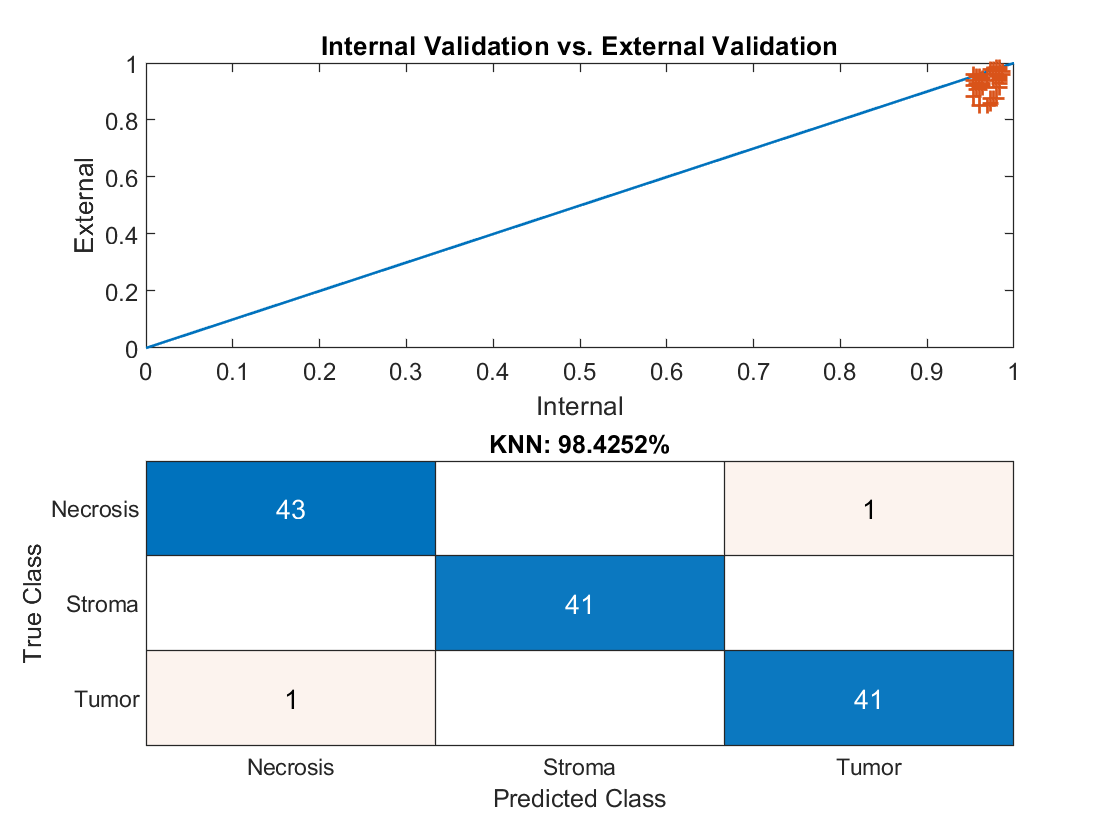

confusionchart(cellstr(Ytest),pred);
title(['KNN: ', num2str(acc), '%'])

## AUC


[X_knn_n,Y_knn_n,T,AUCknn_n] = perfcurve(Ytest,score(:,1),'Necrosis');
[X_knn_s,Y_knn_s,T,AUCknn_s] = perfcurve(Ytest,score(:,2),'Stroma');
[X_knn_t,Y_knn_t,T,AUCknn_t] = perfcurve(Ytest,score(:,3),'Tumor');